#### IEEE 802.11b信道模型

采用指数模型代表2.4GHz室内信道

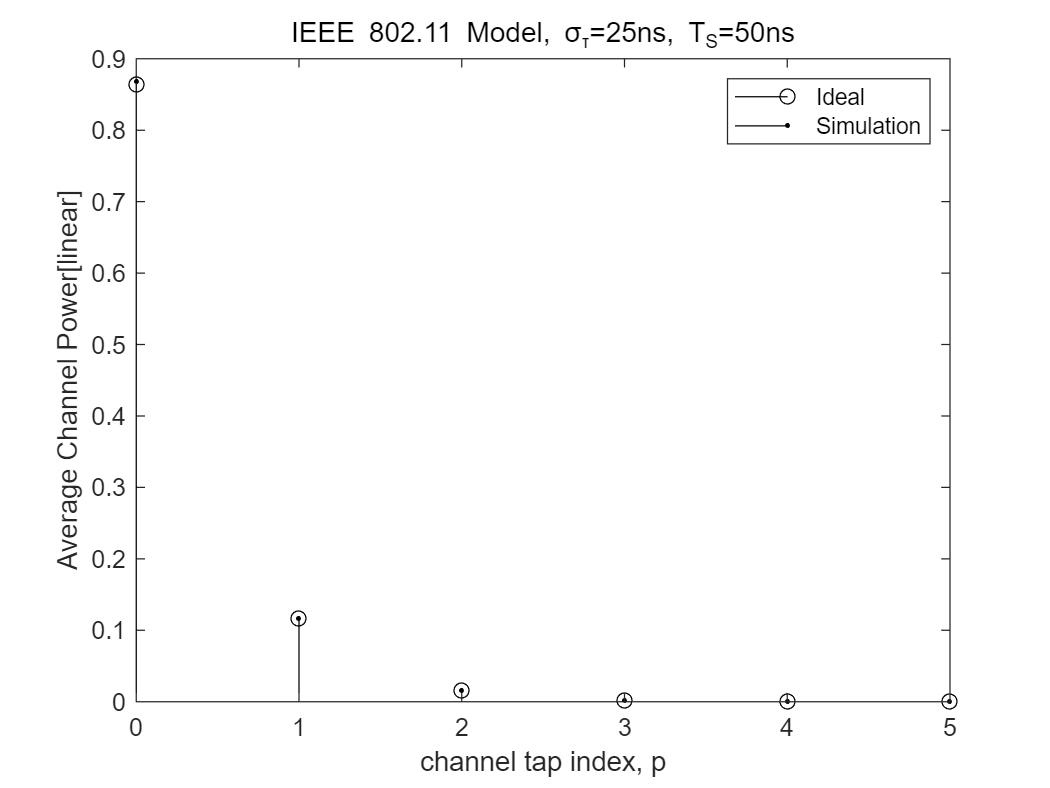

clear;
clc;


scale = 1e-9;
Ts = 50*scale;
t_rms = 25*scale;
num_ch = 10000;
N = 128;%FFT尺寸
PDP = IEEE_802_11_model(t_rms,Ts);
for k=1:length(PDP)
    h(:,k) = Ray_model(num_ch).'*sqrt(PDP(k));
    avg_pow_h(k) = mean(h(:,k).*conj(h(:,k)));
end
H = fft(h(1,:),N);
figure()
stem([0:length(PDP)-1],PDP,'ko')
hold on;
stem([0:length(PDP)-1],avg_pow_h,'k.')
xlabel('channel tap index, p')
ylabel('Average Channel Power[linear]')
title('IEEE 802.11 Model, \sigma_\tau=25ns, T_S=50ns')
legend('Ideal','Simulation')

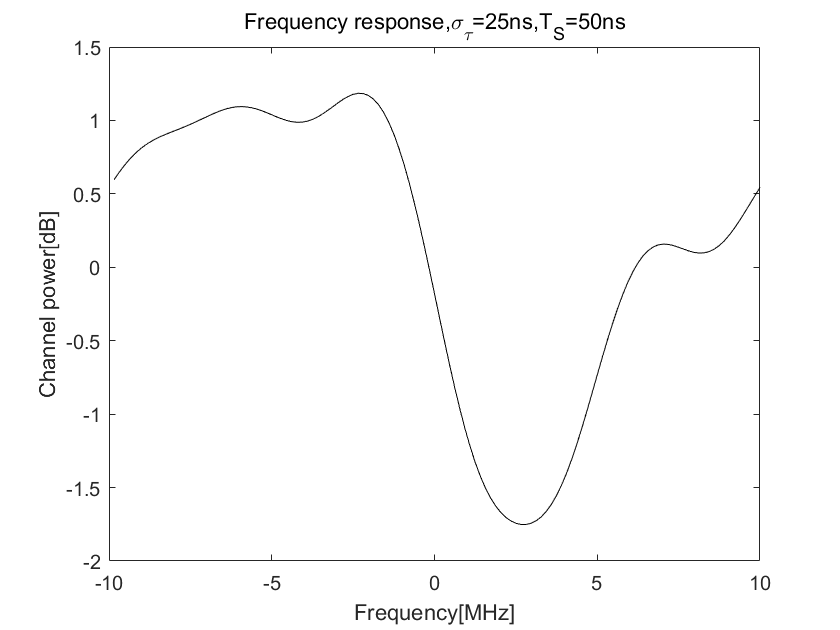

figure()
plot([-N/2+1:N/2]/N/Ts/10^6,10*log10(H.*conj(H)),'K-')
xlabel('Frequency[MHz]')
ylabel('Channel power[dB]')
title('Frequency response,\sigma_\tau=25ns,T_S=50ns')

function PDP = IEEE_802_11_model(sigma_tau,Ts)
%     输入：
%         sigma_tau :RMS时延扩展
%         Ts        :采样时间
%     输出：
%         PDP       :功率时延分布
    lmax = ceil(10*sigma_tau/Ts);
    sigma02 = (1-exp(-Ts/sigma_tau))/(1-exp(-(lmax+1)*Ts/sigma_tau));
    l=0:lmax;
    PDP=sigma02*exp(-l*Ts/sigma_tau);
end

function H=Ray_model(L)
    %输入：
    %       L:信道实现数
    % 输出：
    %         H：信道向量
    H = (randn(1,L)+1j*randn(1,L))/sqrt(2);
end
